## Polarization

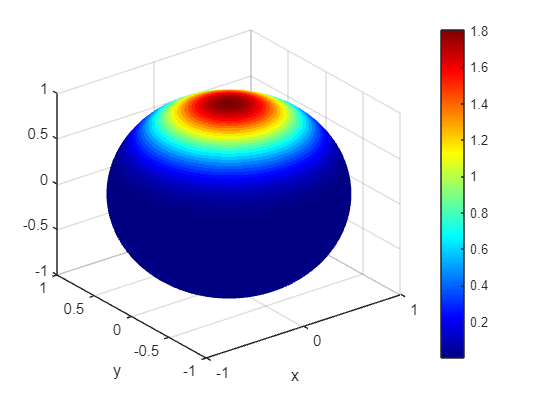

initialState = [1; 0; 0; 0; 0; 0];
rho = initialState*initialState';
wigner_polarize=wigner_plot(rho,100,100);

## $\pi/2$ pulse

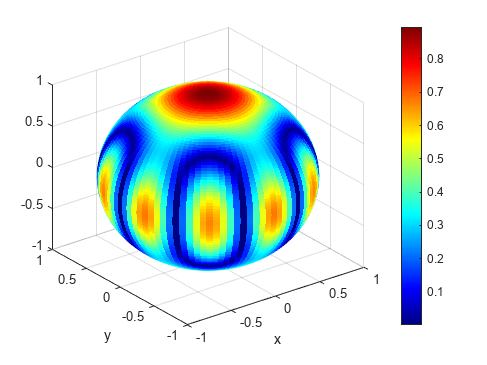

sigmax=spinOp(5/2,'x');
sigmaz=spinOp(5/2,'z');
cat_state=expm(-1i*(sigmax+sigmax^2)*pi/2)*initialState;
rho_cat=cat_state*cat_state';
wigner_cat=wigner_plot(rho_cat,100,100);

## Precession

function output=wigner_plot(rho,theta_num,phi_num)
    % OUTPUT=MATRIX RESULT(THETA,PHI)
    theta_list=[0:pi/theta_num:pi];
    phi_list=[0:2*pi/phi_num:2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            result(i,j)=trace(spin_wigner_operator(5/2,theta,phi)*rho);
        end
    end
    output=abs(result);
    f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,abs(result'));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    %caxis([-1 1]);
    xlabel('x');
    ylabel('y');
    %view([0 90]);
    %set(f1,"Visible","On");
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar;colormap jet
end